**Ercihan Kara - 2375160**

**Eren Kurkut - 2166882**

## Term Project Part 1

Necessary section where fundamental of the project are built for the subsequent parts!

**Listen to the signal and analyze it:**

% listen the signal using autorecorder:
% audiorecorder creates and returns an audiorecorder object with specified properties

% get the frequency of the original chirp to create reference signal
user_int_freq = {'frequency (Hz):'};
title_inp = 'Type the start frequency of the original signal';
dims = [1 80];
defalut_input = {'0'};
freq_input = inputdlg(user_int_freq, title_inp, dims, defalut_input);

samp_rate = 1e+04; % 10000 default, not user-defined, but built-in
bits = 8; % default
channels = 1; % default
ID = -1; % default
temp_freq = freq_input(1);

% object created
obj = audiorecorder(samp_rate, bits, channels, ID);
% start recording using the object
record(obj);

% wait for a key press to stop the recording
disp('press any key to stop recording!');
waitforbuttonpress;

% stop recording and get the recorded data
stop(obj);
data = getaudiodata(obj);

% save the sound data
sound = getaudiodata(obj, 'double');

% play it to check
play(obj);

sound = chirpp;
samp_rate = 1e+04;
% plot in time domain
t = (0:length(sound)-1)/samp_rate;  % Time vector

figure;
plot(t, sound);
xlabel('Time (s)');
ylabel('Amplitude');
title('Original Signal');

% % apply a filter to remove the noise
% % Define the filter specifications
% cutoffFreq = 1000;  % Adjust the cutoff frequency as needed
% filterOrder = 10;  % Adjust the filter order as needed
% 
% % Design a low-pass filter
% lpFilter = designfilt('lowpassfir', 'FilterOrder', filterOrder, 'CutoffFrequency', cutoffFreq, 'SampleRate', samp_rate);
% 
% % Apply the filter to the sound data
% filteredSoundData = filter(lpFilter, sound);
% 
% figure;
% plot(t, filteredSoundData);
% xlabel('Time (s)');
% ylabel('Amplitude');
% title('Filtered Signal');

% the amplitude and duration estimation .
filteredSoundData = sound;
ampl_est = max(abs(filteredSoundData))
duration_est = length(filteredSoundData)/samp_rate

% fft
N = length(chirpp');
frequencies = (0:N-1)*(1e+04/N);  % Frequency vector
signalFFT = fftshift(fft(chirpp'));
fshift = ((-N/2):(N/2)-1)*(1e+04)/N;
amplitudeSpectrum = abs(signalFFT).^2/N;

% Find the frequency with the maximum magnitude
[~, maxIndex] = max(amplitudeSpectrum);
maxFrequency = frequencies(maxIndex)

maxFrequency = 4.9874e+03


temp = ((length(frequencies)-1)/2 - maxIndex)/((length(frequencies)-1)/(1e+04))

temp = 12.5598

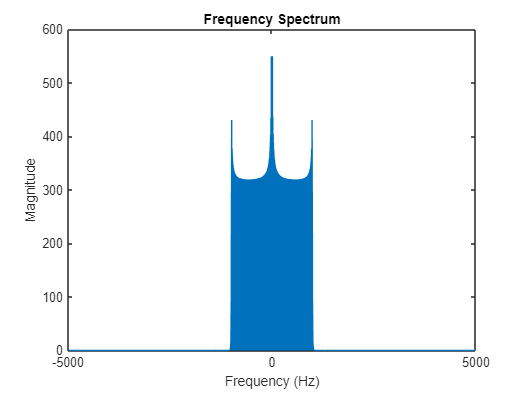

% 1e+04 SAMPLİNG RATE
% cross correlation dene başta ve sonda

figure;
plot(fshift, amplitudeSpectrum);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Spectrum');

% MF detection
% Generate a set of chirp signals with different frequency sweeps and durations
Fs = 1e+04; % Sampling rate in Hz
duration = 1; % Duration of the chirp signals in seconds
fstart = 0; % Start frequency of the chirp signals in Hz
fend = 4000; % End frequency of the chirp signals in Hz
numChirps = 10; % Number of chirp signals to generate
chirpSet = cell(numChirps, 1);
for i = 1:numChirps
    t = linspace(0, duration, Fs*duration);
    f = linspace(fstart, fend, length(t));
    chirpSet{i} = chirp(t, f(1), duration, f(end));
end

% Create a set of matched filters that correspond to the generated chirp signals
matchedFilters = cell(numChirps, 1);
for i = 1:numChirps
    matchedFilters{i} = conj(fliplr(chirpSet{i}));
end

% Convolve the input signal with each of the matched filters in the set
inputSignal = chirpp;
correlationOutputs = zeros(numChirps, length(inputSignal));
for i = 1:numChirps
    correlationOutputs(i,:) = conv(inputSignal, matchedFilters{i}, 'same');
end

% Analyze the correlation outputs to determine which one corresponds to the highest correlation
[maxCorrelation, maxIndex] = max(abs(correlationOutputs), [], 1);

% Determine a threshold for the correlation output to classify the input as a chirp signal or not
threshold = 100;
max(maxCorrelation)

% Classify the input as a chirp signal or not
if max(maxCorrelation) > threshold
    disp(['The input signal is a chirp signal with frequency sweep from ', num2str(fstart), ' Hz to ', num2str(fend), ' Hz.']);
else
    disp('The input signal is not a chirp signal.');
end

% % MF detection
% % % Generate a set of chirp signals with different frequency sweeps and durations
% % Fs = 1e+04; % Sampling rate in Hz
% % duration = 1; % Duration of the chirp signals in seconds
% % fstart = 0; % Start frequency of the chirp signals in Hz
% % fend = 4000; % End frequency of the chirp signals in Hz
% % numChirps = 10; % Number of chirp signals to generate
% % chirpSet = cell(numChirps, 1);
% % for i = 1:numChirps
% %     t = linspace(0, duration, Fs*duration);
% %     f = linspace(fstart, fend, length(t));
% %     chirpSet{i} = chirp(t, f(1), duration, f(end));
% % end
% 
% % Define range of possible chirp parameters
% f0_range = [50, 100, 200]; % start frequency range
% f1_range = [150, 250, 300]; % end frequency range
% T_range = [0.1, 0.2, 0.3]; % duration range
% 
% % Generate a bank of chirp signals
% fs = 10000; % sampling rate
% chirp_bank = {}; % cell array to store chirp signals
% for i = 1:length(f0_range)
%     for j = 1:length(f1_range)
%         for k = 1:length(T_range)
%             f_in = f0_range(i);
%             f_fin = f1_range(j);
%             T = T_range(k);
%             t = 0:1/fs:T;
%             chirp_signal = chirp(t, f_in, T, f_fin);
%             chirp_bank{end+1} = chirp_signal;
%         end
%     end
% end
% 
% % Create a set of matched filters that correspond to the generated chirp signals
% matchedFilters = cell(length(chirp_bank), 1);
% for i = 1:length(chirp_bank)
%     matchedFilters{i} = conj(fliplr(chirp_bank{i}));
% end
% 
% % Convolve the input signal with each of the matched filters in the set
% inputSignal = chirpp;
% correlationOutputs = zeros(length(chirp_bank), length(inputSignal));
% for i = 1:length(chirp_bank)
%     correlationOutputs(i,:) = conv(inputSignal, matchedFilters{i}, 'same');
% end
% 
% % Analyze the correlation outputs to determine which one corresponds to the highest correlation
% [maxCorrelation, maxIndex] = max(abs(correlationOutputs), [], 1);
% 
% % Determine a threshold for the correlation output to classify the input as a chirp signal or not
% threshold = 5000;
% max(maxCorrelation)
% 
% % Classify the input as a chirp signal or not
% if max(maxCorrelation) > threshold
%     disp(['The input signal is a chirp signal']);
% else
%     disp('The input signal is not a chirp signal.');
% end

% % frequency estimation
% % calculate the DFT of the signal
% N = length(filteredSoundData);
% X = fft(filteredSoundData);
% f0 = temp_freq;
% f1 = 5000;
% fs = 1000;
% 
% % CHANGE SAMP_RATE TO 1E+03
% % find the frequency bin index corresponding to f0 and f1
% f = (0:N-1)*(fs/N);  % frequency vector
% f0_idx = find(abs(f-f0)==min(abs(f-f0)));
% f1_idx = find(abs(f-f1)==min(abs(f-f1)));
% 
% % estimate the start and end frequency values
% f_start = f(f0_idx)
% f_end = f(f1_idx)
% bandwidth_est = f_end- f_start

% freq estimation using correlation at initial and end sections
% Generate a bank of sinusoidal signals with varying frequencies
Fs = 1e+04; % Sampling rate in Hz
duration = 1; % Duration of the signals in seconds, total 1e+04 data
numFreqs = 100; % Number of frequencies in the bank
freqs = linspace(0, numFreqs*10, numFreqs); % Frequencies in Hz
sinusoids = cell(numFreqs, 1);
for i = 1:numFreqs
    t = linspace(0, duration, Fs*duration);
    sinusoids{i} = sin(2*pi*freqs(i)*t);
end

% Load the input signal (assuming it's a column vector)
%load('inputSignal.mat'); % Replace with the name of your input signal variable
inp_first = chirpp(1:Fs*duration);
inp_last = chirpp(end-Fs*duration+1:end);
% Cross-correlate the input signal with each sinusoidal signal in the bank
correlations = zeros(numFreqs, 2*length(inp)-1);
for i = 1:numFreqs
    correlations(i,:) = xcorr(inp_last, sinusoids{i});
end

% Find the index of the sinusoidal signal with the highest correlation
[maxCorrelation, maxIndex] = max(max(abs(correlations), [], 2))
freqs(maxIndex)

% autocorrelation for periodicity estimation
plot(xcorr(chirpp));

Unrecognized function or variable 'chirpp'.

title("autocorrelation")
% MERKEZDEKİ HARİÇ 4 TANE VAR, 4 PERİOD; perioddan sonra freq rate hesabı
% yap!!!
[~, locs] = findpeaks(xcorr(chirpp));
perioddd = locs(1) % Index of the first local maximum
%mxx = maxk(xcorr(filteredSoundData), 20);
% Find the indices of the top 5 maximum elements
[mxx, idx] = maxk(xcorr(chirpp), 10)

% MF DETECTION ANOTHER

% Define range of possible chirp parameters
f0_range = [50, 100, 200]; % start frequency range
f1_range = [150, 250, 300]; % end frequency range
T_range = [0.1, 0.2, 0.3]; % duration range

% Generate a bank of chirp signals
fs = 10000; % sampling rate
chirp_bank = {}; % cell array to store chirp signals
for i = 1:length(f0_range)
    for j = 1:length(f1_range)
        for k = 1:length(T_range)
            f0 = f0_range(i);
            f1 = f1_range(j);
            T = T_range(k);
            t = 0:1/fs:T;
            chirp_signal = chirp(t, f0, T, f1);
            chirp_bank{end+1} = chirp_signal;
        end
    end
end

% Filter noisy signal using each chirp signal in the bank
mf_outputs = zeros(size(chirpp));
for i = 1:length(chirp_bank)
    chirp_signal = chirp_bank{i};
    mf_ir = conj(fliplr(chirp_signal));
    mf_outputs(i,:) = filter(mf_ir, 1, chirpp);
end

% Find the peak in the matched filter outputs
[max_val, idx] = max(abs(mf_outputs(:)))
[chirp_idx, sample_idx] = ind2sub(size(mf_outputs), idx)
detection_time = sample_idx / fs

% % CONSIDER
% % Pre-process the input signal
% input_signal = input_signal-mean(input_signal); % DC removal
% input_signal = input_signal/max(abs(input_signal)); % Normalization